T_cnew_t = eye(4);
T_cnew_t(:,4) = [0,0.5,0.5,1]

T_cnew_t =     1.0000         0         0         0
         0    1.0000         0    0.5000
         0         0    1.0000    0.5000
         0         0         0    1.0000


T_w_t = eye(4);
T_w_t(:,4) = [2,2,2,1]

T_w_t =      1     0     0     2
     0     1     0     2
     0     0     1     2
     0     0     0     1


T_w_c = eye(4);
T_w_c(:,4) = [1,0,0,1]

T_w_c =      1     0     0     1
     0     1     0     0
     0     0     1     0
     0     0     0     1


T_w_a = eye(4);
T_w_a(:,4) = [1.25,1,0,1]

T_w_a =     1.0000         0         0    1.2500
         0    1.0000         0    1.0000
         0         0    1.0000         0
         0         0         0    1.0000


% T_cnew_c = eye(4)
T_w_cnew = inv(T_cnew_t)*T_w_t;
T_c_cnew = inv(T_w_c)*T_w_cnew;
T_w_anew = T_c_cnew*T_w_a

T_w_anew =     1.0000         0         0    2.2500
         0    1.0000         0    2.5000
         0         0    1.0000    1.5000
         0         0         0    1.0000


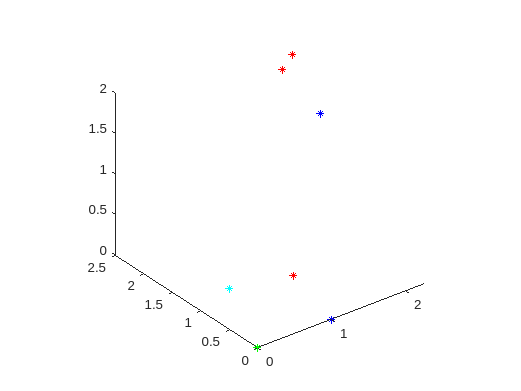

clf
plot3(0,0,0, "g*"); hold on;
plot3(T_cnew_t(1,4), T_cnew_t(2,4), T_cnew_t(3,4), "c*"); hold on;
plot3(T_w_t(1,4), T_w_t(2,4), T_w_t(3,4), "r*")
plot3(T_w_c(1,4), T_w_c(2,4), T_w_c(3,4), "b*")
plot3(T_w_cnew(1,4), T_w_cnew(2,4), T_w_cnew(3,4), "b*")
plot3(T_w_a(1,4), T_w_a(2,4), T_w_a(3,4), "r*")
plot3(T_w_anew(1,4), T_w_anew(2,4), T_w_anew(3,4), "r*")
hold off;
axis equal